# ADALINE time series prediction

This exercise demonstrates the construction and application of ADALINE for adaptive prediction of time series based on past time series data.

Time series is composed of two different segments (different amplitude and frequency), and an ADALINE neural network is constructed to adaptively learn to predict the next step of the time series. 

ADALINE progressively learns to predict correctly the time series, until t = 3 sec, when a new dynamic is introduced and the ADALINE needs to adapt to the new segment.

Visualization of results shows how the training progressively reduces the prediction error and how new adaptation is required at time t = 3 sec to accommodate new dynamics.

2022 © Primož Potočnik ([University of Ljubljana](https://www.uni-lj.si), [Faculty of Mechanical Engineering](https://www.fs.uni-lj.si))

## Define input and output data

close all, clear, clc, format compact

Define segments of time vector

dt = 0.01;          % time step [seconds]
t1 = 0    : dt : 3; %    first time vector [seconds]
t2 = 3+dt : dt : 6; %   second time vector [seconds]
t = [t1 t2];        % complete time vector [seconds]


Time series y is composed of two different segments with different amplitude and frequency. 

y = [sin(4.1*pi*t1) .8*sin(8.3*pi*t2)];

Plot time series signal y

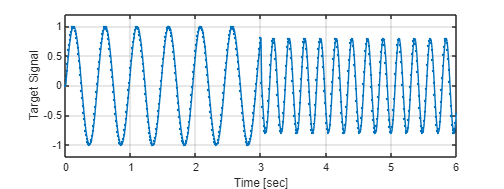

plot(t,y,'.-')
xlabel('Time [sec]');
ylabel('Target Signal');
grid on
ylim([-1.2 1.2])
p = get(gcf,'Position');
set(gcf,'Position',[p(1:3) p(4)/2])

## Prepare data for neural network toolbox

There are two basic types of input vectors: those that occur concurrently (at the same time, or in no particular time sequence), and those that occur sequentially in time. For concurrent vectors, the order is not important, and if there were a number of networks running in parallel, you could present one input vector to each of the networks. For sequential vectors, the order in which the vectors appear is important. 

Y = con2seq(y);

## Define ADALINE neural network

ADALINE neural network is constructed by using 'linearlayer' function. 

The resulting network will predict the next value of the target signal using delayed values of the target.

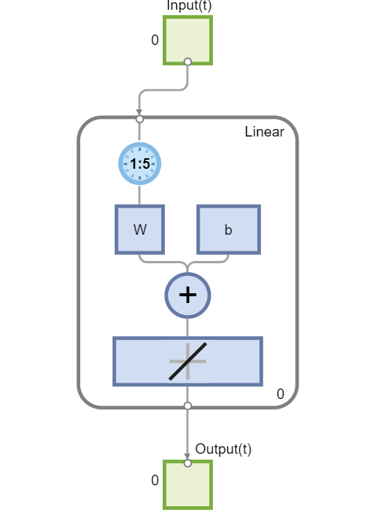

inputDelays   = 1:5; % delayed inputs to be used
learning_rate = 0.2; % learning rate

% define ADALINE
net = linearlayer(inputDelays,learning_rate);

% view ADALINE network
view(net);

See ADALINE network architecture (notice that inputs and outputs are not yet configured).

## Adaptive learning of the ADALINE

ADALINE neural network is adaptively trained to predict the next step of the time series.

Given an input sequence with N steps the network is updated as follows. Each step in the sequence of  inputs is presented to the network one at a time. The network's weight and bias values are updated after each step, before the next step in the sequence is presented. Thus the network is updated N times. The output signal and the error signal are returned, along with the new network.

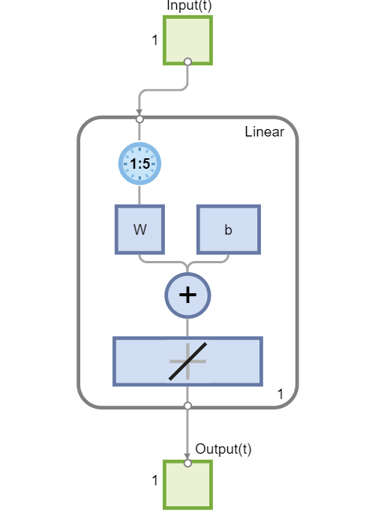

[net,P,E] = adapt(net,Y,Y);

% view trained ADALINE network
view(net)

See the final network parameters, weights (iw), and biases (b), after adaptation:

iw = net.IW{1}

iw =     0.7179    0.4229    0.1552   -0.1203   -0.4159


b  = net.b{1}

b = -1.2520e-08

Adaptive learning can be repeated for further fine-tunning

## Plot results

Visualization of results shows how the training progressively reduces the prediction error and how new adaptation is required at time t = 3 sec to accommodate new dynamics.

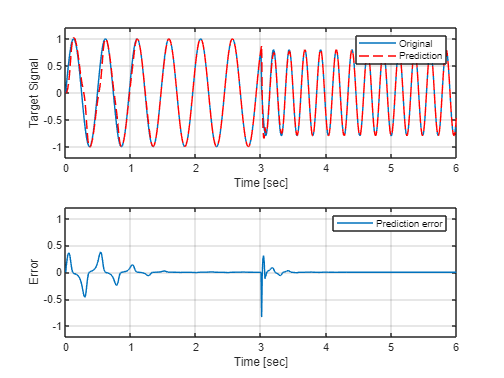

% transform predictions
p = seq2con(P); p = p{1};
e = seq2con(E); e = e{1};

% start a new figure
figure

% first graph
subplot(211)
plot(t,y, t,p,'r--');
legend('Original','Prediction')
grid on
xlabel('Time [sec]');
ylabel('Target Signal');
ylim([-1.2 1.2])

% second graph
subplot(212)
plot(t,e);
grid on
legend('Prediction error')
xlabel('Time [sec]');
ylabel('Error');
ylim([-1.2 1.2])

% close all windows
close all force

## PowerPoint presentation

[NN3a_Perceptron_and_Adaline.pptx](matlab:open('./NN3a_Perceptron_and_Adaline.pptx'))